DOE optimisation code. Created by Thomas Dixon 04/04/2024

## **Step 1: **Set the design space limits (lower and upper bounds of each variable)

clear all
%                 [Time (S), Conc (mg ml-1)]
variableBounds =  [10, 0.01;     % LB
                   60, 0.05]       % UB

variableBounds =    10.0000    0.0100
   60.0000    0.0500



numbOfVars = size(variableBounds,2);

## **Step 2**: Define the parameters

experiments = readtable("ExperimentsRuhex2D.xlsx")

experiments = 13×4 table
    ExperimentNumber    Time_S    Concentration_Mg_mL    Iruhex_NA
    ________________    ______    ___________________    _________

            1             60             0.05             -87.646 
            2             60             0.05             -58.774 
            3             60             0.05             -73.983 
            4             60             0.01              -31.95 
            5             10             0.01              -35.02 
            6             10             0.05              -115.8 
            7             30             0.03             -50.305 
            8             10             0.01             -28.465 
            9             10             0.01              -33.47 
           10             10             0.05             -60.883 
           11             30      

experimentNumb = experiments{:,1};
experimentDesignSpaceModel = experiments{:,2:3};


## Step 3: Select desired results

exclude = 1;

%2D DOE
if exclude == 1
    selectedExps = 1:11;

%2D DOE with model validation points
elseif exclude == 2
    selectedExps = 1:13;
end

experimentDesignSpace = experimentDesignSpaceModel(selectedExps,:);

## **Step 4:** Plot the design space

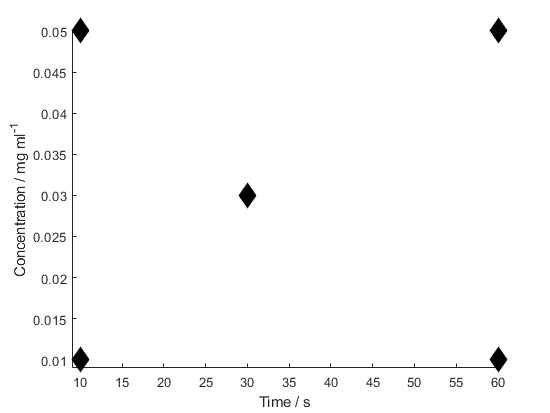

scatter(experimentDesignSpace(:,1), experimentDesignSpace(:,2), 200, 'filled', "kd")
xlabel("Time / s")
ylabel("Concentration / mg ml^{-1}")

xlim([9, 60])
ylim([0.009, 0.05])

saveas(gca, "DesignSpace2D.png")

## Step 5: Set the response value (IRuhex) for each condition run

logged = false;

if logged
    responsesTemp = log(experiments{:,end}*-1); %Last column in csv file
else
    responsesTemp = experiments{:,end};
end

responses = responsesTemp(selectedExps);
responsesNorm = experiments{selectedExps,end};

## **Step 6: **Plot design space with response

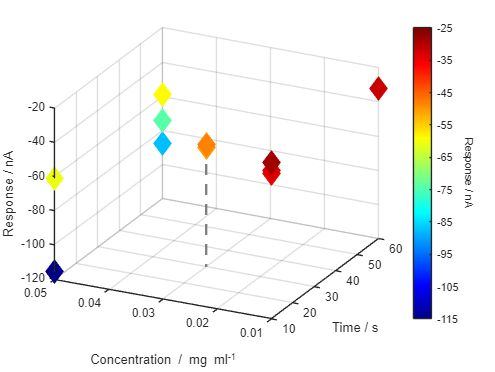

scatter3(experimentDesignSpace(:,1), experimentDesignSpace(:,2), responsesNorm, 200, responsesNorm, "d", "filled")
ylabel("Concentration / mg ml^{-1}")
xlabel("Time / s")
zlabel("Response / nA")
colormap(jet)

hold on
scatter3([-10,-10], [-10,-10], [-25,-115], 200, [-25,-115], "d", "filled")

if exclude == 1
    plot3([experimentDesignSpace(end,1) experimentDesignSpace(end,1)], [experimentDesignSpace(end,2) experimentDesignSpace(end,2)], [responsesNorm(end), -120], "Color","#808080","LineWidth",2, "LineStyle","--")
elseif exclude == 2
    plot3([experimentDesignSpace(end,1) experimentDesignSpace(end,1)], [experimentDesignSpace(end,2) experimentDesignSpace(end,2)], [responsesNorm(end), -120], "Color","#808080","LineWidth",2, "LineStyle","--")
    plot3([experimentDesignSpace(end-1,1) experimentDesignSpace(end-1,1)], [experimentDesignSpace(end-1,2) experimentDesignSpace(end-1,2)], [responsesNorm(end-1), -120], "Color","#808080","LineWidth",2, "LineStyle","--")
    plot3([experimentDesignSpace(end-2,1) experimentDesignSpace(end-2,1)], [experimentDesignSpace(end-2,2) experimentDesignSpace(end-2,2)], [responsesNorm(end-2), -120], "Color","#808080","LineWidth",2, "LineStyle","--")
end
hold off

grid on

h = colorbar;
h.Label.String = "Response / nA";
h.Label.Rotation = 270;
h.Label.VerticalAlignment = "bottom";

xlim([10 60])

view([-63.61 27.65])

h.Limits = [-115,-25];
set(h, 'Ticks', round(linspace(-115, -25, 10))); % Set the ticks on the color bar
saveas(gca, "DesignSpaceWithResponse2DzaxisResp.png")

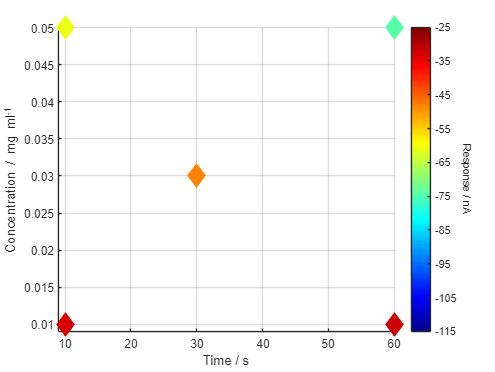

scatter(experimentDesignSpace(:,1), experimentDesignSpace(:,2), 200, responsesNorm, "d", "filled")
ylabel("Concentration / mg ml^{-1}")
xlabel("Time / s")
zlabel("Response / nA")
colormap(jet)

hold on
scatter([-10,-10], [-10,-10], 200, [-25,-115], "d", "filled")
hold off

grid on

h = colorbar;
h.Label.String = "Response / nA";
h.Label.Rotation = 270;
h.Label.VerticalAlignment = "bottom";

h.Limits = [-115,-25];
set(h, 'Ticks', round(linspace(-115, -25, 10))); % Set the ticks on the color bar

xlim([9 60])
ylim([0.009 0.05])

saveas(gca, "DesignSpaceWithResponse2D.png")

## **Step 7: **Fit model and plot different response surfaces

model = 'interactions';

[LB, UB] = bounds(experimentDesignSpace(:,1:2),1);
normalisedResults = (experimentDesignSpace(:,1:2) - LB)./(UB-LB);
mdl = fitlm(normalisedResults, responses, model)

mdl = Linear regression model:
    y ~ 1 + x1*x2

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    ________    _________

    (Intercept)    -31.056     9.6427     -3.2207     0.014639
    x1              1.6304     19.645    0.082995      0.93618
    x2             -55.392     15.587     -3.5538    0.0092959
    x1:x2           12.192      24.88     0.49002       0.6391


Number of observations: 11, Error degrees of freedom: 7
Root Mean Squared Error: 17.1
R-squared: 0.719,  Adjusted R-Squared: 0.599
F-statistic vs. constant model: 5.97, p-value = 0.0242

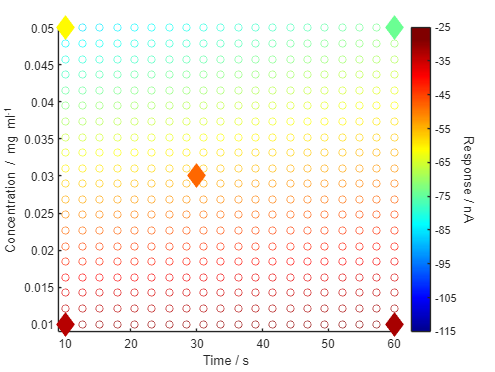


varInterval = 20;
for var = 1:numbOfVars
    spacing(:,var) = {linspace(variableBounds(1,var), variableBounds(2,var), varInterval)};
end

combs = permn(1:varInterval,numbOfVars);
for var = 1:numbOfVars
    gridSearch(:,var) = spacing{1,var}(combs(:,var));
end

gridSearchNorm = (gridSearch- LB)./(UB-LB);

matrixPred= predict(mdl, gridSearchNorm);

if logged == 1
    matrixPred = exp(matrixPred)*-1;
end

scatter(gridSearch(:,1), gridSearch(:,2), [], matrixPred)
hold on
scatter(experimentDesignSpace(:,1), experimentDesignSpace(:,2), 200, responsesNorm, "d", "filled")
hold off
colormap(jet)
xlabel("Time / s")
ylabel("Concentration / mg ml^{-1}")

h = colorbar;
h.Label.String = "Response / nA";
h.Label.Rotation = 270;
h.Label.VerticalAlignment = "bottom";
h.Label.FontSize = 11;

h.Limits = [-115,-25];
set(h, 'Ticks', round(linspace(-115, -25, 10))); % Set the ticks on the color bar

xlim([9 60])
ylim([0.009 0.05])

saveas(gca, "DesignSpaceWithResponseSurface2D.png")

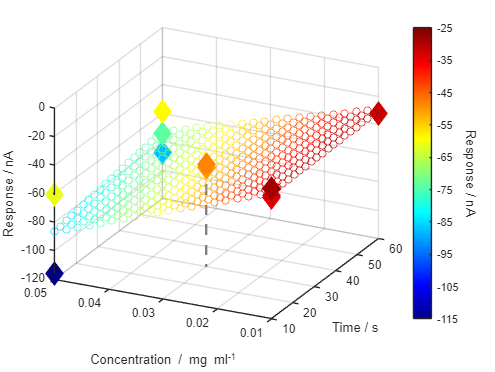

scatter3(gridSearch(:,1), gridSearch(:,2), matrixPred, [], matrixPred)

hold on
scatter3(experimentDesignSpace(:,1), experimentDesignSpace(:,2), responsesNorm, 200, responsesNorm, "d", "filled")

if exclude == 1
    plot3([experimentDesignSpace(end,1) experimentDesignSpace(end,1)], [experimentDesignSpace(end,2) experimentDesignSpace(end,2)], [responsesNorm(end), -120], "Color","#808080","LineWidth",2, "LineStyle","--")
elseif exclude == 2
    plot3([experimentDesignSpace(end,1) experimentDesignSpace(end,1)], [experimentDesignSpace(end,2) experimentDesignSpace(end,2)], [responsesNorm(end), -120], "Color","#808080","LineWidth",2, "LineStyle","--")
    plot3([experimentDesignSpace(end-1,1) experimentDesignSpace(end-1,1)], [experimentDesignSpace(end-1,2) experimentDesignSpace(end-1,2)], [responsesNorm(end-1), -120], "Color","#808080","LineWidth",2, "LineStyle","--")
    plot3([experimentDesignSpace(end-2,1) experimentDesignSpace(end-2,1)], [experimentDesignSpace(end-2,2) experimentDesignSpace(end-2,2)], [responsesNorm(end-2), -120], "Color","#808080","LineWidth",2, "LineStyle","--")
end

hold off

colormap(jet)
xlabel("Time / s")
ylabel("Concentration / mg ml^{-1}")
zlabel("Response / nA")

hold on
scatter([-10,-10], [-10,-10], 200, [-25,-115], "d", "filled")
hold off

h = colorbar;
h.Label.String = "Response / nA";
h.Label.Rotation = 270;
h.Label.VerticalAlignment = "bottom";
h.Label.FontSize = 11;

xlim([10 60])
%ylim([0.01 0.04])

view([-63.61 27.65])

h.Limits = [-115,-25];
set(h, 'Ticks', round(linspace(-115, -25, 10))); % Set the ticks on the color bar
saveas(gca, "DesignSpaceWithResponseSurface2DzaxisResp.png")

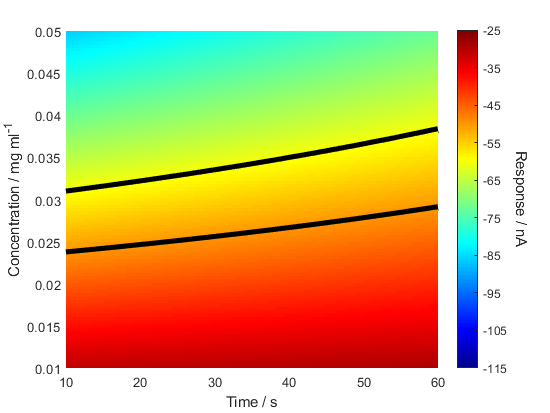

[X,Y] = meshgrid(linspace(variableBounds(1,1), variableBounds(2,1), 100), linspace(variableBounds(1,2), variableBounds(2,2), 100));

Xnorm = (X - min(X, [], "all"))./(max(X, [], "all")-min(X, [], "all"));
Ynorm = (Y - min(Y, [], "all"))./(max(Y, [], "all")-min(Y, [], "all"));

Z = mdl.Coefficients.Estimate(1) + mdl.Coefficients.Estimate(2).*Xnorm + mdl.Coefficients.Estimate(3).*Ynorm + mdl.Coefficients.Estimate(4).*Xnorm.*Ynorm;

if logged == 1
    Z = exp(Z)*-1;
end

surf(X, Y, Z, "EdgeColor","texturemap")

hold on
scatter([-10,-10], [-10,-10], 200, [-25,-115], "d", "filled")
hold off

XBound = linspace(variableBounds(1,1), variableBounds(2,1), 10);
XBoundNorm = (XBound - min(XBound))./(max(XBound) - min(XBound));

YBound1Norm = (-50 - mdl.Coefficients.Estimate(1) - mdl.Coefficients.Estimate(2).*XBoundNorm)./(mdl.Coefficients.Estimate(3) + mdl.Coefficients.Estimate(4).*XBoundNorm);
YBound2Norm = (-60 - mdl.Coefficients.Estimate(1) - mdl.Coefficients.Estimate(2).*XBoundNorm)./(mdl.Coefficients.Estimate(3) + mdl.Coefficients.Estimate(4).*XBoundNorm);

if logged == 1
    YBound1Norm = (log((-50)*-1) - mdl.Coefficients.Estimate(1) - mdl.Coefficients.Estimate(2).*XBoundNorm)./(mdl.Coefficients.Estimate(3) + mdl.Coefficients.Estimate(4).*XBoundNorm);
    YBound2Norm = (log((-60)*-1) - mdl.Coefficients.Estimate(1) - mdl.Coefficients.Estimate(2).*XBoundNorm)./(mdl.Coefficients.Estimate(3) + mdl.Coefficients.Estimate(4).*XBoundNorm);
end

YBound1 =  YBound1Norm*(variableBounds(2,2)-variableBounds(1,2)) + variableBounds(1,2);
YBound2 =  YBound2Norm*(variableBounds(2,2)-variableBounds(1,2)) + variableBounds(1,2);

hold on
plot3(XBound, YBound1, ones(10, 1)*-50, "LineWidth", 5, "Color", "k")
plot3(XBound, YBound2, ones(10, 1)*-60, "LineWidth", 5, "Color", "k")

scatter3(30*ones(1,length(responsesNorm)), 0.03*ones(1,length(responsesNorm)), -100*ones(length(responsesNorm),1),100, responsesNorm, "d", "filled");
hold off
colormap(jet)
colorbar
xlabel("Time / s")
ylabel("Concentration / mg ml^{-1}")
ylim([0.01 0.05])
zlabel("Response")

h = colorbar;
h.Label.String = "Response / nA";
h.Label.Rotation = 270;
h.Label.VerticalAlignment = "bottom";
h.Label.FontSize = 11;

h.Limits = [-115,-25];
set(h, 'Ticks', round(linspace(-115, -25, 10))); % Set the ticks on the color bar

ylim([0.01 0.05])
view([0 90.0])

saveas(gca, "DesignSpaceWithResponseSurfaceSlice2D.png")

This code finds the permitations, you can ignore this (i did not write it)

function [M, I] = permn(V, N, K)
% PERMN - permutations with repetition
%   Using two input variables V and N, M = PERMN(V,N) returns all
%   permutations of N elements taken from the vector V, with repetitions.
%   V can be any type of array (numbers, cells etc.) and M will be of the
%   same type as V.  If V is empty or N is 0, M will be empty.  M has the
%   size numel(V).^N-by-N. 
%
%   When only a subset of these permutations is needed, you can call PERMN
%   with 3 input variables: M = PERMN(V,N,K) returns only the K-ths
%   permutations.  The output is the same as M = PERMN(V,N) ; M = M(K,:),
%   but it avoids memory issues that may occur when there are too many
%   combinations.  This is particulary useful when you only need a few
%   permutations at a given time. If V or K is empty, or N is zero, M will
%   be empty. M has the size numel(K)-by-N. 
%
%   [M, I] = PERMN(...) also returns an index matrix I so that M = V(I).
%
%   Examples:
%     M = permn([1 2 3],2) % returns the 9-by-2 matrix:
%              1     1
%              1     2
%              1     3
%              2     1
%              2     2
%              2     3
%              3     1
%              3     2
%              3     3
%
%     M = permn([99 7],4) % returns the 16-by-4 matrix:
%              99     99    99    99
%              99     99    99     7
%              99     99     7    99
%              99     99     7     7
%              ...
%               7      7     7    99
%               7      7     7     7
%
%     M = permn({'hello!' 1:3},2) % returns the 4-by-2 cell array
%             'hello!'        'hello!'
%             'hello!'        [1x3 double]
%             [1x3 double]    'hello!'
%             [1x3 double]    [1x3 double]
%
%     V = 11:15, N = 3, K = [2 124 21 99]
%     M = permn(V, N, K) % returns the 4-by-3 matrix:
%     %        11  11  12
%     %        15  15  14
%     %        11  15  11
%     %        14  15  14
%     % which are the 2nd, 124th, 21st and 99th permutations
%     % Check with PERMN using two inputs
%     M2 = permn(V,N) ; isequal(M2(K,:),M)
%     % Note that M2 is a 125-by-3 matrix
%
%     % PERMN can be used generate a binary table, as in
%     B = permn([0 1],5)  
%
%   NB Matrix sizes increases exponentially at rate (n^N)*N.
%
%   See also PERMS, NCHOOSEK
%            ALLCOMB, PERMPOS, NEXTPERM, NCHOOSE2 on the File Exchange
% tested in Matlab 2018a
% version 6.2 (jan 2019)
% (c) Jos van der Geest
% Matlab File Exchange Author ID: 10584
% email: samelinoa@gmail.com
% History
% 1.1 updated help text
% 2.0 new faster algorithm
% 3.0 (aug 2006) implemented very fast algorithm
% 3.1 (may 2007) Improved algorithm Roger Stafford pointed out that for some values, the floor
%   operation on floating points, according to the IEEE 754 standard, could return
%   erroneous values. His excellent solution was to add (1/2) to the values
%   of A.
% 3.2 (may 2007) changed help and error messages slightly
% 4.0 (may 2008) again a faster implementation, based on ALLCOMB, suggested on the
%   newsgroup comp.soft-sys.matlab on May 7th 2008 by "Helper". It was
%   pointed out that COMBN(V,N) equals ALLCOMB(V,V,V...) (V repeated N
%   times), ALLCMOB being faster. Actually version 4 is an improvement
%   over version 1 ...
% 4.1 (jan 2010) removed call to FLIPLR, using refered indexing N:-1:1
%   (is faster, suggestion of Jan Simon, jan 2010), removed REPMAT, and
%   let NDGRID handle this
% 4.2 (apr 2011) corrrectly return a column vector for N = 1 (error pointed
%    out by Wilson).
% 4.3 (apr 2013) make a reference to COMBNSUB
% 5.0 (may 2015) NAME CHANGED (COMBN -> PERMN) and updated description,
%   following comment by Stephen Obeldick that this function is misnamed
%   as it produces permutations with repetitions rather then combinations.
% 5.1 (may 2015) always calculate M via indices
% 6.0 (may 2015) merged the functionaly of permnsub (aka combnsub) and this
%   function
% 6.1 (may 2016) fixed spelling errors
% 6.2 (jan 2019) fixed some coding style warnings
narginchk(2, 3) ;
if fix(N) ~= N || N < 0 || numel(N) ~= 1
    error('permn:negativeN','Second argument should be a positive integer') ;
end
nV = numel(V) ;
if nargin==2 
    %% PERMN(V,N) - return all permutations
    if nV == 0 || N == 0
        M = zeros(nV, N) ;
        I = zeros(nV, N) ;
    elseif N == 1
        % return column vectors
        M = V(:) ;
        I = (1:nV).' ;
    else
        % this is faster than the math trick used with 3 inputs below
        [Y{N:-1:1}] = ndgrid(1:nV) ;
        I = reshape(cat(N+1, Y{:}), [], N) ;
        M = V(I) ;
    end
else
    %% PERMN(V,N,K) - return a subset of all permutations
    nK = numel(K) ;
    if nV == 0 || N == 0 || nK == 0
        M = zeros(numel(K), N) ;
        I = zeros(numel(K), N) ;
    elseif nK < 1 || any(K<1) || any(K ~= fix(K))
        error('permn:InvalidIndex','Third argument should contain positive integers.') ;
    else
        V = reshape(V, 1, []) ; % v1.1 make input a row vector
        nV = numel(V) ;
        Npos = nV^N ;
        if any(K > Npos)
            warning('permn:IndexOverflow', ...
                'Values of K exceeding the total number of combinations are saturated.')
            K = min(K, Npos) ;
        end
             
        % The engine is based on version 3.2 with the correction
        % suggested by Roger Stafford. This approach uses a single matrix
        % multiplication.
        B = nV.^(1-N:0) ;
        I = ((K(:)-.5) * B) ; % matrix multiplication
        I = rem(floor(I), nV) + 1 ;
        M = V(I) ;
    end
end
% Algorithm using for-loops
% which can be implemented in C or VB
%
% nv = length(V) ;
% C = zeros(nv^N,N) ; % declaration
% for ii=1:N,
%     cc = 1 ;
%     for jj=1:(nv^(ii-1)),
%         for kk=1:nv,
%             for mm=1:(nv^(N-ii)),
%                 C(cc,ii) = V(kk) ;
%                 cc = cc + 1 ;
%             end
%         end
%     end
% end


end
